# **MATLAB COVID-19 Data Analysis Challenge Part 1**

complemented by **Juergen Kanz, 2020, **[https:\\about.me\juergenkanz](https:\\about.me\juergenkanz)

This script will guide you through the import and formating tasks required to participate in the challenge. 

Once you complete your own data analysis and make your own visualizations in Section IV, follow the instructions in Section V to share your work!

In your analysis, you will access data from the [COVID-19 Data Repository by the Center for Systems Science and Engineering (CSSE) at Johns Hopkins University.](https://github.com/CSSEGISandData/COVID-19)

## I. Set Up Your Environment

**This section summarizes content that is provided in the **[**accompanying video**](https://youtu.be/nfAzUqpGpug)**. Please watch the video before proceeding.**

Complete these tasks before you import data:

1. Install a command-line Git client. For help, see the [Set Up Git Source Control](https://www.mathworks.com/help/matlab/matlab_prog/set-up-git-source-control.html) section of the MATLAB documentation.

2. Set up a MATLAB Project:

- On the toolstrip under the **Home** tab, click **New **--> **Project **--> **From Git**

- Enter the GitHub URL as the **Repository Path**: [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

- Create a new Sandbox Folder (**Sandbox**) called `COVID19analysis`.

3. Save this Live Script file in your **Sandbox**.

4. Generate an import function:

- Click **Import Data **(on the toolstrip under the **Home** tab), navigate to the folder `csse_covid_19_daily_reports`, and select a global daily reports .csv file more recent than May 29, 2020. 

- Click **Generate Function** and rename the function` importCOVIDfile`.

- Click **Save As...** and save the function in your **Sandbox.**

5. If you close MATLAB and wish to continue work on your data analysis, open your MATLAB Project file before you do anything else. This makes your** Sandbox** the current folder.

- To re-open this document: open your Project then open this Live Script from the **Current Folder** Broswer**.**

- To download the most recent data: open your Project then click **Pull** (on the toolstrip under the **Project** tab)

## II. Import the Data

Before running the code in this section, verify that your** Current Folder** *contains* the folder `csse_covid_19_data `as well as a MATLAB function file (.m) with your generated function, `importCOVIDfile`.

% Create a datastore with parameters set by import function "importCOVIDfile" -- Expect to see a warning because not all of the data is similarly formatted
% The wildcard operator (*) allows you to select all of the .csv files in the directory
covidDatastore = datastore("csse_covid_19_data\csse_covid_19_daily_reports\*.csv","Type","file","ReadFcn",@importCOVIDfile2,"UniformRead",true);


% Remove data from before April 07, 2020 (first 76 files) (irregularly formatted data)
covidDatastore.Files = covidDatastore.Files(77:end);


% Read data from Datastore into Workspace
dataRaw = readall(covidDatastore);
head(dataRaw)

ans = 8×14 table
      FIPS       Admin2      Province_State      Country_Region        Last_Update         Lat       Long_     Confirmed    Deaths    Recovered    Active              Combined_Key               Incidence_Rate    CaseFatality_Ratio
    _________    ______    __________________    ______________    ___________________    ______    _______    _________    ______    _________    ______    _________________________________    ______________    __________________

    {'45001'}     NaN      {'South Carolina'

## **III. Data Analysis and Visualization -- Getting Started**

In this section, you'll be reviewing concepts from [Practical Data Science with MATLAB](https://www.coursera.org/specializations/practical-data-science-matlab) to complete a few tasks. Completing these tasks will help you start your data analysis and visualization.

### Filter the Data

Use the dropdown controls in the interactive data table at the end of the last section` (``dataRaw``) `to select data from July 12, 2020. Then, below the table, click **Copy**. Paste the copied code below. Change the name of this new variable to `dataFiltered1``.`

% Data for July 12, 2020

% The John Hopkins University updates the data always in the night of the
% following day. This means we have to take the day of interest and add one
% day for the selection in the Last_Update Column.

dataFiltered1 = dataRaw(dataRaw.Last_Update >= '2020-07-13 00:00:00' & dataRaw.Last_Update <= '2020-07-13 23:59:59' | ismissing(dataRaw.Last_Update),:);
head(dataFiltered1)

ans = 8×14 table
      FIPS       Admin2      Province_State      Country_Region        Last_Update         Lat       Long_     Confirmed    Deaths    Recovered    Active              Combined_Key               Incidence_Rate    CaseFatality_Ratio
    _________    ______    __________________    ______________    ___________________    ______    _______    _________    ______    _________    ______    _________________________________    ______________    __________________

    {'45001'}     NaN      {'South Carolina'

Make a new data table with only those locations that have more than 150,000 confirmed cases on July 12, 2020. Use the dropdown controls in the table above` (``dataFiltered1``) `to select the rows with more than 150,000 confirmed cases. Then click **Copy**, paste the code below, and change the name of this new variable to `dataFiltered2`.

dataFiltered2 = dataFiltered1(dataFiltered1.Confirmed >= 150000 | ismissing(dataFiltered1.Confirmed),:);
head(dataFiltered2)

ans = 8×14 table
       FIPS       Admin2     Province_State      Country_Region        Last_Update          Lat       Long_     Confirmed     Deaths    Recovered       Active               Combined_Key              Incidence_Rate    CaseFatality_Ratio
    __________    ______    _________________    ______________    ___________________    _______    _______    __________    ______    __________    __________    _______________________________    ______________    __________________

    {'36061' }     NaN      {'New 

### **Plot the Filtered Data on a Map**

Now plot some of the filtered data on a map. First, make a geobubble plot with data from `dataFiltered1`**. **Set the `"SizeVariable" `to` "Confirmed" `in order to see the confirmed cases**.**

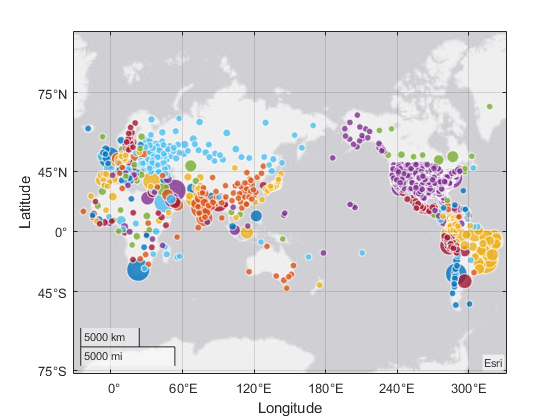

geobubble(dataFiltered1.Lat,dataFiltered1.Long_,dataFiltered1.Confirmed,dataFiltered1.Country_Region)

Next, make another geobubble plot with the data from `dataFiltered2``. `Show the confirmed cases on the map, as before. Now, only those locations with more than 150,000 confirmed cases are represented on the map.

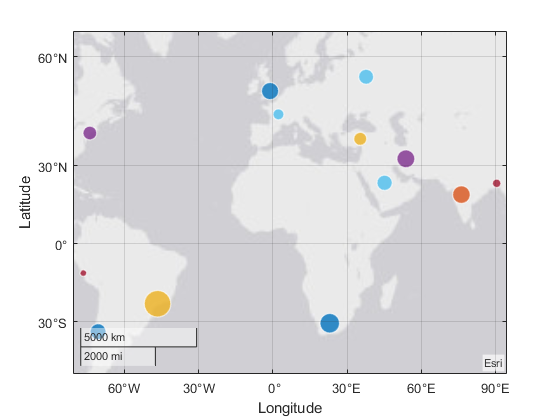


geobubble(dataFiltered2.Lat,dataFiltered2.Long_,dataFiltered2.Confirmed,dataFiltered2.Country_Region)

### Aggregate the Data

Use the `groupsummary` function to aggregate by **Country** and **Date**. Return the **sum** and the** mean **of the **confirmed cases**, **case fatality ratio**, **latitude**, and **longitude**. The sum operation is helpful for the confirmed cases while the mean operation is helpful for the case fatality ratio. Also, the mean latitude and longitude will give you the rough location for the center of each country.

Note: to use multiple grouping variables (`groupvars`), multiple grouping functions (`methods`), or to group multiple data variables (`datavars`), enter arrays of multiple strings as the arguments of `groupsummary`.  For example, enter` ["Country_Region","Last_Update"] `as the argument for `groupvars``.` Your code should be in this format: `groupsummary(dataRaw,[groupvars],[methods],[datavars])`

For additional help, see the "Multiple Grouping Variables" example of the [groupsummary](https://www.mathworks.com/help/matlab/ref/double.groupsummary.html) section of the MATLAB documentation.


dataBins = groupsummary(dataRaw,["Country_Region","Last_Update"],["sum","mean"],["Confirmed","CaseFatality_Ratio","Lat","Long_"],'IncludeMissingGroups',true);
head(dataBins)

ans = 8×11 table
    Country_Region        Last_Update        GroupCount    sum_Confirmed    mean_Confirmed    sum_CaseFatality_Ratio    mean_CaseFatality_Ratio    sum_Lat    mean_Lat    sum_Long_    mean_Long_
    ______________    ___________________    __________    _____________    ______________    ______________________    _______________________    _______    ________    _________    __________

     Afghanistan      2020-04-07 23:04:29        1              423              423                    0                         NaN              33.939      33.939       67.71        67.71   
     Afghanistan      2020

## **IV. Data Analysis and Visualization**

Now, it is your turn to analyze and visualize the data. Use the techniques outlined above as well as others to create new analyses and visualizations.

Some questions and ideas to get you started:

- How do you remove the variables that won't be of use in the table produced by `groupsummary`? (Hint: check out the function `removevars`)

- Are there problems or complications presented by using the `Last_Update` variable to select which date(s) to represent? (Recall: the dates in the `Last_Update` column are typically one day ahead of the date given in the filename).

- Look at the other folders (i.e. other than the global daily reports) pulled into your Sandbox. There is a folder of time series data and a folder of US daily reports data (grouped by state). How could you import and use this data for your analyses and visualizations?

- Try changing some variable names and types in the import tool *before *pressing **Generate Function**. Now your import function will update the names and variable types when you load the data into the datastore.

- If you use `groupsummary `to find the mean of the latitutude and of the longitude, some countries (such as France) have location data that does not make sense. This is because these countries have territories in locations that are not near one another. How could you fix this?

- If you use `groupsummary `to find the mean of the latitude and of the longitude, the new variables are called `mean_Lat` and `mean_Long_`. How could you rename these to `Lat` and `Lon`?

- Apply **filters **to the table produced by `groupsummary `to identify global trends.

- Create plots that show change over time.

Here are a few images of example plots. These were created using the following functions: 

`bar();`

`geobubble();`

`area();`

`plot();`

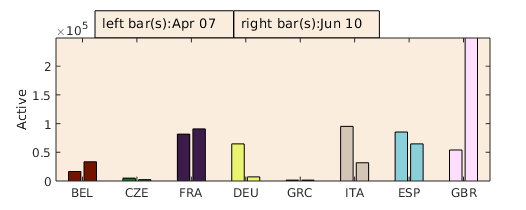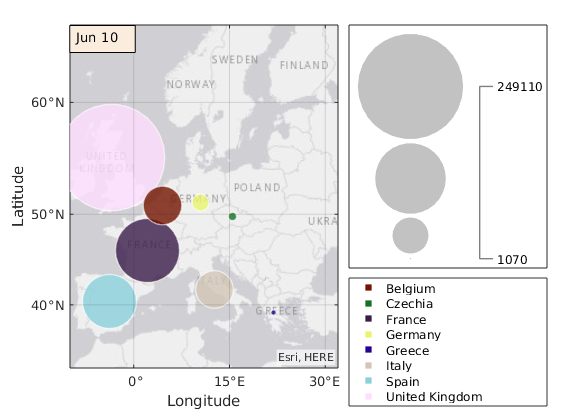

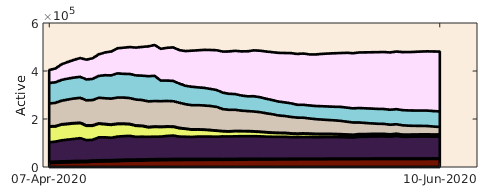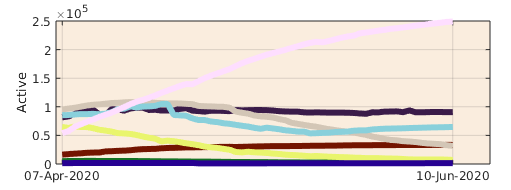

Now it is your turn to be creative. What questions do you want to answer? What insights can you find to share with others? Use the space below to analyze and visualize the data.

% next step

edit COVID19analysisPart2.mlx

## V. Share your Work

Once you've explored the data and made some new visualizations, share your work: 

- Email your final report as a PDF to [matlab-challenge@groups.mathworks.com](mailto:matlab-challenge@groups.mathworks.com). 

- Share your reports with your social networks. Make sure to tag us @MATLAB @MathWorks #MATLAB #MathWorks. 

- Share work with classmates by visiting the discussion forum for [Exploratory Data Analysis with MATLAB](https://www.coursera.org/learn/exploratory-data-analysis-matlab)*. *Look for the pinned forum post and share your plots. 

**Be creative! We will choose exceptional reports to highlight in our courses**. We look forward to seeing your analysis. 